%实例、导弹追踪
%{
位于坐标原点的A船向位于其正东方20个单位的B船发射导弹，
导弹始终对准B船，B船以时速v单位沿东北方向逃逸。
若导弹的速度为3v，导弹的射程为50，
画出导弹运行的曲线，导弹是否能在射程内集中B船？


采用的是微分法，也就是说每1e-8s计算一次，可以将曲线看成直线
%}
clear;clc
tic
v=200; %任意给定v的值
dt=1e-8; %定义时间间隔，就是多长时间计算一次
x=[0,20]; %初始化导弹和B船的横坐标分别为x(1)和x(2)
y=[0,0]; %初始化导弹和B船的纵坐标分别为y(1)和y(2)
t=0; %初始化导弹击落B船的时间
d=0; %初始化导弹飞行的距离
m=sqrt(2)/2;   % 将sqrt(2)/2定义为一个常量，更加简洁
Distance=sqrt((x(2)-x(1))^2+(y(2)-y(1))^2); % 导弹与B船的距离
 
plot(x(1),y(1),'r.','MarkerSize',0.5);
grid on;
hold on;
plot(x(2),y(2),'b.','MarkerSize',1);
hold on;
 
axis([0 30 0 10])  %固定x轴的范围为0-30  固定y轴的范围为0-10
k=0;  %引入一个变量  为了控制画图的速度（因为Matlab中画图的速度超级慢）
 
while(Distance>=1e-5)  %当距离大于1e-5时都会进行下面的循环
    t=t+dt; %更新导弹击落B船的时间
    d=d+3*v*dt; %更新导弹飞行的距离
    x(2)=20+t*v*m;  
    y(2)=t*v*m; %计算B船的新位置
    Distance=sqrt((x(2)-x(1))^2+(y(2)-y(1))^2); %更新导弹与B船的距离
    tan_alpha=(y(2)-y(1))/(x(2)-x(1)); %根据导弹与B的位置计算导弹的方向，即tan(α)
    cos_alpha=(x(2)-x(1))/Distance;   
    sin_alpha=(y(2)-y(1))/Distance;  
    x(1)=x(1)+3*v*dt*cos_alpha;  
    y(1)=y(1)+3*v*dt*sin_alpha; %计算导弹的新位置
    
    k = k +1 ;  
    
    if mod(k,2000) == 0   % 每刷新1000次时间就画出下一个导弹和B船所在的坐标  mod(m,n)表示求m/n的余数
        plot(x(1),y(1),'r.','MarkerSize',0.5);%'MarkerSize'表示标记的大小
        hold on;
        plot(x(2),y(2),'b.','MarkerSize',1);
        hold on;
        pause(0.001);  % 暂停0.001s后再继续下面的操作
    end
    
    if d>50  % 导弹的有效射程为50个单位
        disp('导弹没有击中B船');
        break;  % 退出循环
    end
    
    if d<=50 && Distance<1e-5  % 导弹飞行的距离小于50个单位且导弹和B船的距离小于临界距离
        disp(['导弹飞行',num2str(d),'单位后击中B船'])
        disp(['导弹飞行的时间为',num2str(t*60),'分钟'])
    end
end

导弹飞行27.8033单位后击中B船


导弹飞行的时间为2.7803分钟


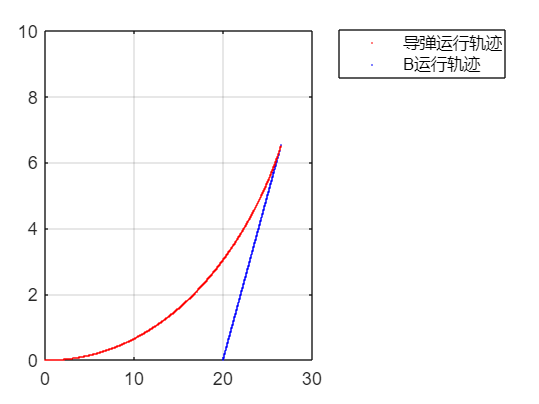

 
legend('导弹运行轨迹','B运行轨迹','Location','NortheastOutside');

toc

历时 75.185389 秒。
